#                    Numerical Analysis

###                          Non-Linear Equation System

                                                1401/07/30   

clc;  clear; close all;


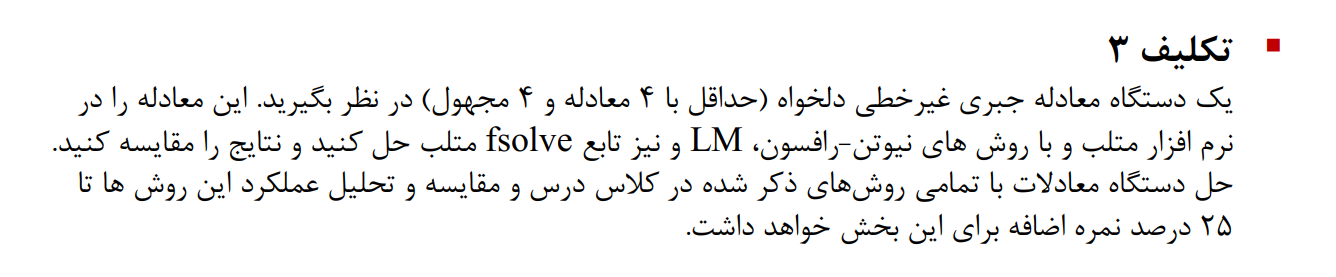

## Newton Method

% Step 1:
 XO=0; XO2=0;  XAR =0; XP=0;

A = [1 1 1 2;...
     2 1 -4 12*XP^2;...
     2 -1*XO 0 0;...
     -5 0 3.14 XP];

B = [-1; 0 ; 0 ; 0];

% Step 2:
syms x1 x2 x3 x4

f1(x1,x2,x3,x4) = x1+x2+x3+2*x4-1;
f2(x1,x2,x3,x4) = 2*x1+x2-4*x3+12*x4^3;
f3(x1,x2,x3,x4) = 2*x1-x2^2 ;
f4(x1,x2,x3,x4) = -5*x1+3.14*x3+x4^2;

% Step 3:

J(x1,x2,x3,x4) = ...
    [ (diff(f1,x1))  (diff(f1,x2))  (diff(f1,x3))  (diff(f1,x4));...
      (diff(f2,x1))  (diff(f2,x2))  (diff(f2,x3))  (diff(f2,x4));...
      (diff(f3,x1))  (diff(f3,x2))  (diff(f3,x3))  (diff(f3,x4));...
      (diff(f4,x1))  (diff(f4,x2))  (diff(f4,x3))  (diff(f4,x4))] ; 


F(x1,x2,x3,x4) = [(f1(x1,x2,x3,x4)); ...
                    (f2(x1,x2,x3,x4));(f3(x1,x2,x3,x4));(f4(x1,x2,x3,x4))]

$$F(x1, x2, x3, x4) = \left(\begin{array}{c} x_{1}+x_{2}+x_{3}+2\,x_{4}-1\\ 12\,{x_{4}}^{3}+2\,x_{1}+x_{2}-4\,x_{3}\\ 2\,x_{1}-{x_{2}}^{2}\\ {x_{4}}^{2}-5\,x_{1}+\frac{157\,x_{3}}{50} \end{array}\right)$$


iter=1e2;
epsilon0 = 1e-2 ;
tic;
for i=1:iter
[X] = [XO  XO2  XAR XP]' - inv(double(J(XO,XO2,XAR,XP))) *F(XO,XO2,XAR,XP); %[double(f1(XO,XO2,XAR,XP)); ...
                   % double(f2(XO,XO2,XAR,XP));double(f3(XO,XO2,XAR,XP));double(f4(XO,XO2,XAR,XP))];

if(norm(X-[XO  XO2  XAR XP]')<  epsilon0  )
    break;
end

XO  = X(1) ;
XO2 = X(2) ;
XAR = X(3) ;
XP  = X(4) ;


end
delta_T_Newton = toc;
% Function:
disp(double(F(XO,XO2,XAR,XP)))

   1.0e-03 *

    0.0000
    0.3036
   -0.0415
    0.0749



disp("For X = ")

For X = 


disp(double(X))

    0.1177
    0.4852
    0.1838
    0.1067



disp("Time Elapsed:  "+delta_T_Newton)

Time Elapsed:  0.23416


## MATLAB Solve

syms xo2 xo xar xp
eq1 = xo2 +xo +xar - 1+2*xp;
eq2 = 2*xo2 +xo -4*xar+12*xp^3;
eq3 = 2*xo2 - xo^2;
eq4 = xp^2-5*xo2+3.14*xar;
tic;

sol = solve(eq1,eq2,eq3,eq4); 
delta_T_solve =toc;
sol.xo

$$ans = \begin{array}{l} \left(\begin{array}{c} -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,1\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,1\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,1\right)}{1093}+\frac{686}{1093}\\ -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,2\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,2\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,2\right)}{1093}+\frac{686}{1093}\\ -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,3\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,3\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,3\right)}{1093}+\frac{686}{1093}\\ -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,4\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,4\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,4\right)}{1093}+\frac{686}{1093}\\ -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,5\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,5\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,5\right)}{1093}+\frac{686}{1093}\\ -\frac{4884\,{\mathrm{root}\left(\sigma_{1},z,6\right)}^{3}}{1093}-\frac{300\,{\mathrm{root}\left(\sigma_{1},z,6\right)}^{2}}{1093}-\frac{1372\,\mathrm{root}\left(\sigma_{1},z,6\right)}{1093}+\frac{686}{1093} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{6}+\frac{50\,z^{5}}{407}+\frac{281077\,z^{4}}{496947}-\frac{416503\,z^{3}}{993894}+\frac{231071\,z^{2}}{5963364}-\frac{99665\,z}{1987788}+\frac{63697}{11926728} \end{array}$$

[double(sol.xo(end)), double(sol.xo2(end)) , double(sol.xar(end)) , double(sol.xp(end))]

ans =   -1.6442 + 0.5640i   1.1926 - 0.9273i   2.0889 - 1.3071i  -0.3187 + 0.8352i


disp("Time Elapsed:  "+delta_T_solve)

Time Elapsed:  0.1329


##   MATLAB fsolve

fun =@root4d

fun = function_handle with value:
    @root4d


X0 = [0,0,0,0] ;
tic;
sol_fsolve = fsolve(fun,X0);  


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


delta_T_fsolve = toc;

Equation solved. 

The sum of squared function values, r = 6.233773e-20, is less than

                                                    sqrt(options.FunctionTolerance) = 1.000000e-03. 

The relative norm of the gradient of r,

                                                    9.053595e-10, is less than options.OptimalityTolerance = 1.000000e-06.

disp("Solution from fsolve is : ")

Solution from fsolve is : 


disp(sol_fsolve)

    0.1486    0.3855    0.2170    0.2489



The Function value is:

disp(root4d(sol_fsolve))

   1.0e-09 *

   -0.0000    0.2481   -0.0055    0.0277



disp("Time Elapsed:  "+delta_T_fsolve)

Time Elapsed:  0.040037


## LM Method

The Levenberg-Marquardt method **acts more like a gradient-descent method when the parameters are far from their optimal value**, and acts more like the Gauss-Newton method when the parameters are close to their optimal value.

The Levenberg-Marquardt algorithm was developed in the early 1960’s to solve nonlinear least squares problems.

This objective may be minimized with respect to the parameters in one step via the solution to a linear matrix equation. If the fit function is not linear in its parameters, the least squares problem requires an iterative solution algorithm.     

The Levenberg-Marquardt algorithm combines two numerical minimization algorithms: 

1) The gradient descent method and the

2) Gauss-Newton method.  

In the Gauss-Newton method, the sum of the squared errors is reduced by assuming the least squares function is locally quadratic in the parameters, and finding the minimum of this quadratic.  

**The Levenberg-Marquardt Method**:::::

     The Levenberg-Marquardt algorithm adaptively varies the parameter updates between the gradient descent update and the Gauss-Newton update, 

  

where **small values** of the *damping parameter **λ *result in a **Gauss-Newton** update and **large**

**values** of  *λ *result in a **gradient descent** update.

    Above,  J  is the [Jacobian matrix](https://en.wikipedia.org/wiki/Jacobian_matrix_and_determinant), whose  i-th row equals  Ji , and where   f (β)  and  y are vectors with  i-th component  f(xi ,β) and  yi                   respectively. 

    The above expression obtained for  β  comes under the Gauss–Newton method. The Jacobian matrix as defined  above is not (in general) a square matrix, but a rectangular matrix of  size    m×n , where  n is the number of parameters (size of the vector β ). The matrix multiplication 

(JTJ)

yields the required  n×n square matrix and the matrix-vector product on the right hand side yields a vector of size n. 

The result is a set of  n linear equations, which can be solved for δ. 

The (non-negative) damping factor  λ is adjusted at each iteration.

### Generate Random Data:

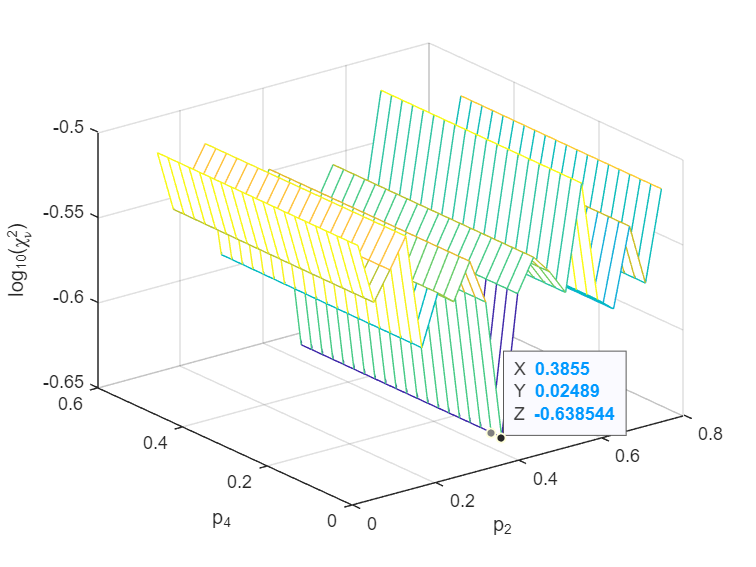


consts = [ 3]; % optional vector of constants
Npnt = 100;	 % number of data points
t = [1:Npnt]'; % independent variable, column vector
p_true  = [ 0.1486    0.3855    0.2170    0.2489 ]'; %[  6   20   1   5 ]';     
Npar = length(p_true);
msmnt_err = 0.5;

y_dat = lm_func(t,p_true,3);
y_dat = y_dat + msmnt_err*randn(Npnt,1);  % add random measurement errors

tic;
% range of values for gridded paramter search
p1 = 0.1*p_true(1):0.1*p_true(1):2*p_true(1);
p2 = 0.1*p_true(2):0.1*p_true(2):2*p_true(2);
p3 = 0.1*p_true(3):0.1*p_true(3):2*p_true(3);
p4 = 0.1*p_true(4):0.1*p_true(4):2*p_true(4);

% gridded parameter search
for ip2 = 1:length(p2);
   for ip4 = 1:length(p4);
	pt = [ p_true(1)  p2(ip2) p_true(3) p4(ip4) ];
	delta_y = ( y_dat - lm_func(t,pt,consts) );
	X2(ip2,ip4) = (delta_y' * delta_y)/(Npnt-Npar);  % reduced chi-sq.
   end
end

figure(1); % ------------ plot shape of Chi-squared objective function
clf
mesh(p2,p4,log10(X2))
xlabel('p_2')
ylabel('p_4')
zlabel('log_{10}(\chi^2_\nu)','rotation',90)
hold on

plotfile = ['lm_example',int2str(3),'.eps'];


delta_T_LM = toc;
disp("Time Elapsed:  "+ delta_T_LM)

Time Elapsed:  0.1455


Above, it can be seen that p2 is correctly estimated, almost around 0.4! --> True value was 0.38! --> Also correct value of p4 is available in global pint where p2 is 0.4 and p4 is 0.2 almost!

function F4 = root4d(x)

F4(1) = x(1)+x(2)+x(3)+x(4)-1;
F4(2) = 2*x(1) +x(2)-4*x(3)+12*x(4)^3;
F4(3) = 2*x(1)-2*x(2)^2;
F4(4) = -5*x(1)+3.14*x(3)+x(4)^2;
end

